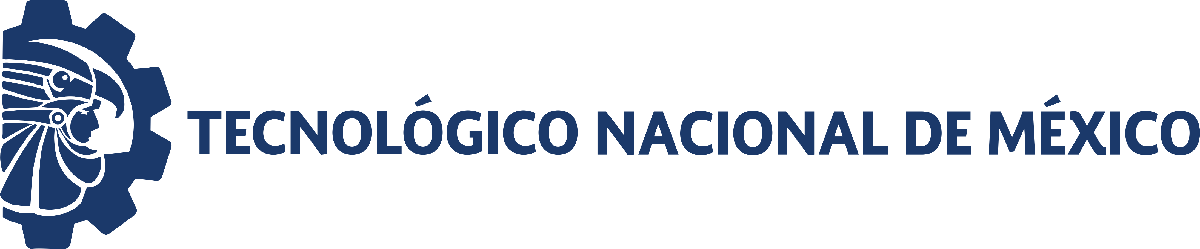                                 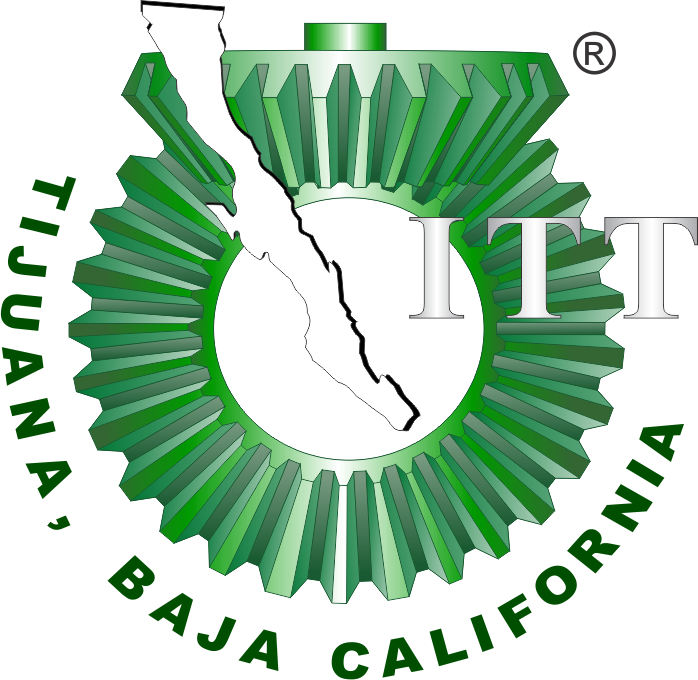

# Práctica 4: Modelizado matematico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

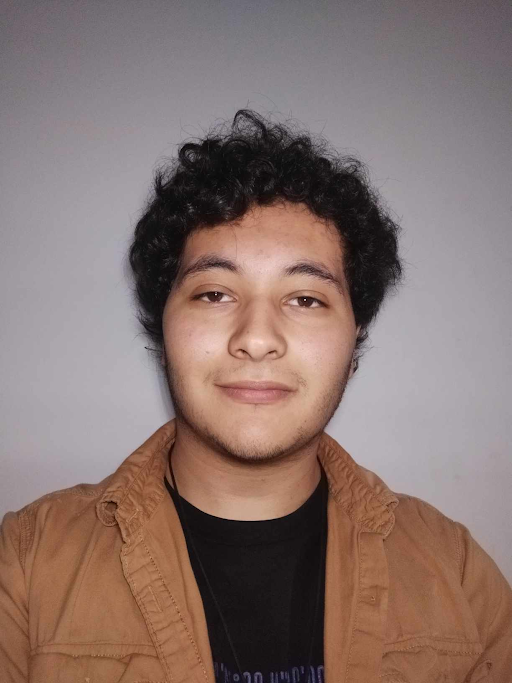

Nombre del alumno: **Hector Andres Fernandez Esquivel**

Número de control: **21212153**

Correo institucional: **l21212153@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

    Time     x(t):      y(t): 
    ____    _______    _______

      0     0.83086    0.99501
      5       1.662     2.5145
     10      2.2956     4.8358
     15       2.837     6.9758
     20      3.9255     6.9853
     25      3.9262     7.2348
     30      4.7409     6.7614
     35      4.5751     6.3823
     40      5.2588     6.3545
     45      5.1664     6.1724
     50      5.8318     6.0549
     55       6.006     4.8586
     60      5.8311     5.5353
     65      5.8493      5.113
     70      6.5819     5.3388
     75      6.8798     4.7416
     80      6.3799     4.5736
     85      6.8302     4.7893
     90      6.6908     4.1221
     95      7.1671     4.3096
    100      7.1736     4.6394
    105      6.6341      4.249
    110      7.3832      4.463
    115      7.5585     4.3067
    120      7.1246     4.1103
    125      7.5308     3.7325
    130      7.2664     4.118

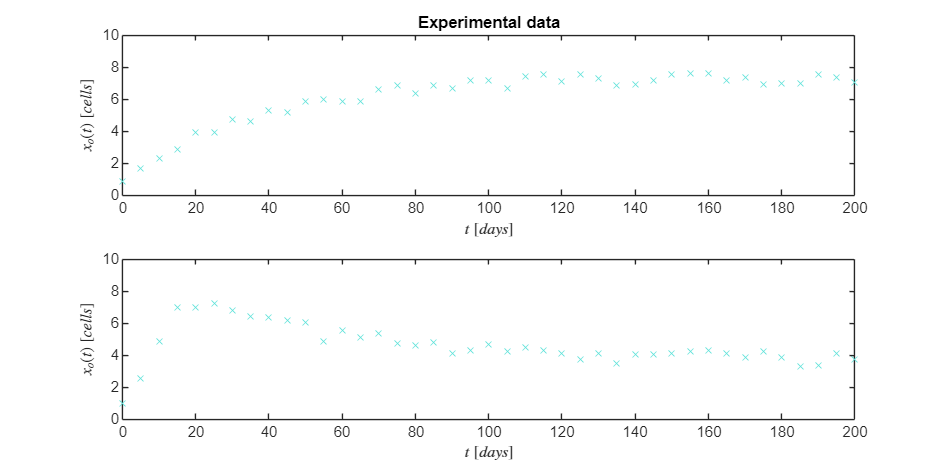

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1); 
xo = sys(:,2); 
yo = sys(:,3);
T = array2table([to,xo,yo],'VariableNames',{'Time','x(t):','y(t):'});
disp(T); plotdata(to,xo,yo) 

## Algoritmos de regresion no lineal


$$\dot{x} =\rho_1 x\left(1-\frac{x+\gamma_1 y}{\beta }\right)$$



$$\dot{y} =\rho_2 y\left(1-\frac{y+\gamma_2 x}{\beta }\right)$$



$$\beta =10$$



Sample size (n): 41
Parameters to be estimated (pars): 4
Degrees of freedom: 78
Significance level (alpha): 0.05
t-Student value: 1.9908
R-squared: 0.97421
Corrected AIC (n/pars < 40): 25.358

    Parameters    Estimate       SE          MoE              CI95             pvalue  
    __________    ________    _________    ________    __________________    __________

      rho1        0.15265     0.0053859    0.010723    0.14193    0.16337    8.0593e-43
      gamma1      0.67149      0.012893    0.025668    0.64582    0.69716    2.3483e-62
      rho2        0.27412      0.011137    0.022173    0.25195     0.2963    1.6195e-38
      gamma2      0.82706     0.0083655    0.016654    0.81041    0.84371    9.9951e-84



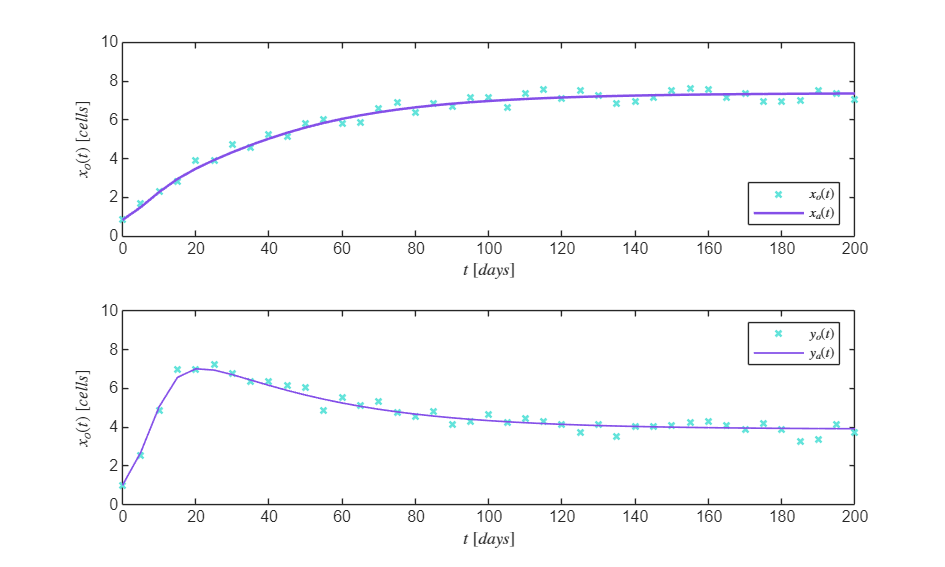

P0 = [0.1;0.1;0.1;0.1];
[mdl, xa, ya] = Variant(to,xo,yo,P0); plotresults(to,[xo,xa],[yo,ya])

## Equilibrium Points and Jacobian matrix

clear; close all; clc
syms x y rho1 gamma1 rho2 gamma2 beta
dx = rho1*x*(1-((x+gamma1*y)/beta));
dy = rho2*y*(1-((y+gamma2*x)/beta));
J = jacobian([dx,dy],[x,y]);
fprintf('Jacobian matrix of the Lotka-Volterra system:'); disp(J)

Jacobian matrix of the Lotka-Volterra system:

$$\left(\begin{array}{cc} -\rho_{1}\,\left(\frac{x+\gamma_{1}\,y}{\beta }-1\right)-\frac{\rho_{1}\,x}{\beta } & -\frac{\gamma_{1}\,\rho_{1}\,x}{\beta }\\ -\frac{\gamma_{2}\,\rho_{2}\,y}{\beta } & -\rho_{2}\,\left(\frac{y+\gamma_{2}\,x}{\beta }-1\right)-\frac{\rho_{2}\,y}{\beta } \end{array}\right)$$

dx = rho1*x*(1-((x+gamma1*y)/beta)) == 0;
dy = rho2*y*(1-((y+gamma2*x)/beta)) == 0;
edos = solve([dx,dy],[x,y]);
fprintf(['The Lotka-Volterra system has ',num2str(length(edos.x)),' equilibrium points.'])

The Lotka-Volterra system has 4 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1);
X1 = edos.x(2); Y1 = edos.y(2);
X2 = edos.x(3); Y2 = edos.y(3);
X3 = edos.x(4); Y3 = edos.y(4);
syms x0 y0 x1 y1 x2 y2 x3 y3
fprintf('Equilibrium points of the Lotka-Volterra system:'); disp([x0,y0,X0,Y0]); disp([x1,y1,X1,Y1]); disp([x2,y2,X2,Y2]); disp([x3,y3,X3,Y3])

Equilibrium points of the Lotka-Volterra system:

$$\left(\begin{array}{cccc} x_{0} & y_{0} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{1} & y_{1} & \beta & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{2} & y_{2} & 0 & \beta \end{array}\right)$$

$$\left(\begin{array}{cccc} x_{3} & y_{3} & \frac{\beta \,\left(\gamma_{1}-1\right)}{\gamma_{1}\,\gamma_{2}-1} & \frac{\beta \,\left(\gamma_{2}-1\right)}{\gamma_{1}\,\gamma_{2}-1} \end{array}\right)$$

clear rho1 gamma1 rho2 gamma2
rho1 = 0.15265; gamma1 = 0.67149; 
rho2 = 0.27412; gamma2 = 0.82706;
beta = 10;
disp('(x0,y0) = (0,0)'); disp('(x1,y1) = (10,0)'); disp('(x2,y2) = (0,10)'); disp(['(x1,y1) = (',num2str(beta*(gamma1-1)/(gamma1*gamma2-1)),',',num2str(beta*(gamma2-1)/(gamma1*gamma2-1)),')'])

(x0,y0) = (0,0)
(x1,y1) = (10,0)
(x2,y2) = (0,10)
(x1,y1) = (7.3883,3.8895)


### Local stability

clc; clear;
rho1 = 0.15265; gamma1 = 0.67149; 
rho2 = 0.27412; gamma2 = 0.82706;
beta = 10;
syms x y
dx = rho1*x*(1-((x+gamma1*y)/beta)) == 0;
dy = rho2*y*(1-((y+gamma2*x)/beta)) == 0;
edos = solve([dx,dy],[x,y]); 
x0 = double(edos.x(1)); y0 = double(edos.y(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2));
x2 = double(edos.x(3)); y2 = double(edos.y(3));
x3 = double(edos.x(4)); y3 = double(edos.y(4));
clear x y
x = [x0; x1; x2; x3]; y = [y0; y1; y2; y3];
var = {'(x0,y0)'; '(x1,y1)'; '(x2,y2)'; '(x3,y3)'};
Equilibria = table(x,y,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye'};
fprintf('Equilibrium points of the Lotka-Volterra system:\n'); disp(Equilibria)

Equilibrium points of the Lotka-Volterra system:
                 xe        ye  
               ______    ______

    (x0,y0)         0         0
    (x1,y1)        10         0
    (x2,y2)         0        10
    (x3,y3)    7.3883    3.8895



L = zeros(length(x),2);
for i = 1:length(x)
    J = [-rho1*((x(i)/beta)+((gamma1*y(i))/beta)-1)-(rho1*x(i))/beta,         -(gamma1*rho1*x(i))/beta;
                -(gamma2*rho2*y(i))/beta, -rho2*((y(i)/beta)+((gamma2*x(i))/beta)-1)-(rho2*y(i))/beta]
    L(i,:) = eig(J);
end

J =     0.1527         0
         0    0.2741


J =    -0.1527   -0.1025
         0    0.0474


J =     0.0501         0
   -0.2267   -0.2741


J =    -0.1128   -0.0757
   -0.0882   -0.1066


L1 = L(:,1); L2 = L(:,2);
Lambdas = table(L1,L2,'RowNames',var);
disp('Eignen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas)

Eignen values of the Jacobian matrix evaluated at each equilibrium point:
                  L1          L2    
               ________    _________

    (x0,y0)     0.15265      0.27412
    (x1,y1)    -0.15265     0.047406
    (x2,y2)    -0.27412     0.050147
    (x3,y3)    -0.19148    -0.027923




$$\lambda_1 <0<\lambda_2 \;\left(x_0 ,y_0 \right)$$


El primer punto de equilibrio (x0,y0) es altamente inestable dado que ambos valores presentes son reales positivos, aunque el segundo y tercer punto (x1,y1) y (x2,y2) presenta un valor real negativo, estos tambien son inestables y solamente el cuarto punto de equilibrio (x3,y3) es el que presenta una estabilidad al ser dos valores reales negativos presentando un escenario nodo.

### Equilibrium points

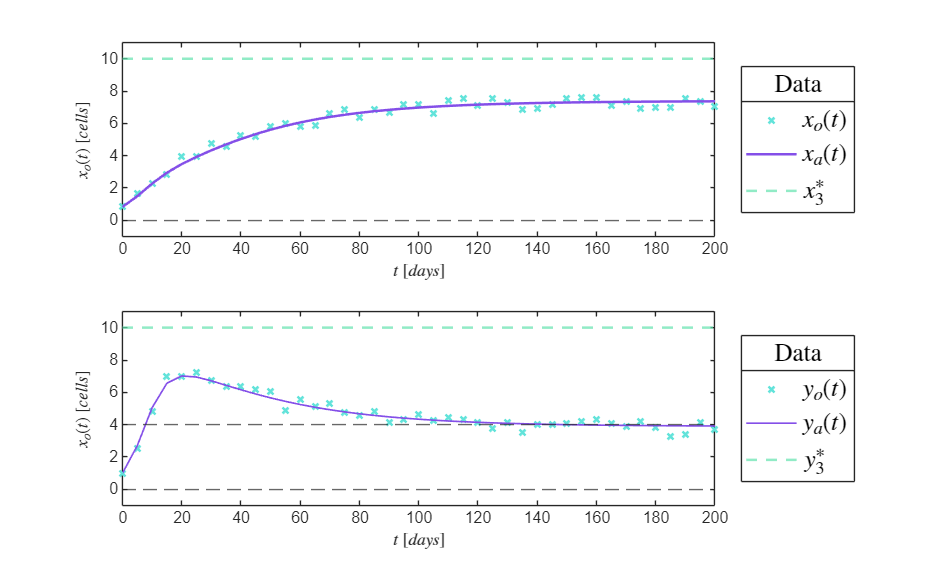

clc; clear; close all;
sys = readmatrix('data.csv');
to = sys(:,1); 
xo = sys(:,2); 
yo = sys(:,3);
rho1 = 0.15265; gamma1 = 0.67149; 
rho2 = 0.27412; gamma2 = 0.82706;
P0 = [rho1,gamma1,rho2,gamma2];
[mdl, xa, ya] = Varied(to,xo,yo,P0); plotreseqs(to,[xo,xa],[yo,ya])

## Functions

function plotdata(t,x,y)
    clf;
    set(figure(1),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')
    NGS = [98,227,218; 98,154,227; 132,79,232; 98,227,174;]/255;
    hold on; box on; grid off; colororder(NGS)

    subplot(2,1,1);
    plot(t,x,'x','MarkerSize',5)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    title('Experimental data')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)

    subplot(2,1,2);
    plot(t,y,'x','MarkerSize',5)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
end

function plotresults(t,x,y)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;

    subplot(2,1,1)
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1.5,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','On')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)

    subplot(2,1,2)
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','Best','Box','On')
    xlim([0 200]); xticks(0:20:200)
    ylim([0 10]); yticks(0:2:10)
end

function plotreseqs(t,x,y)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')
    beta = 10;
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(2,1,1)
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1.5,'Color',c2)
    yline(beta,'--','LineWidth',1.5,'Color',c3)
    yline(0,'--')
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$x_o(t)$','$x_a(t)$','$x^*_3$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)

    subplot(2,1,2)
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    yline(beta,'--','LineWidth',1.5,'Color',c3)
    yline(0,'--')
    yline(4,'--')
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$y_o(t)$','$y_a(t)$','$y^*_3$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([0 200]); xticks(0:20:200)
    ylim([-1 11]); yticks(0:2:10)
end

### Modelling

function [mdl,xa,ya] = Variant(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        rho1 = p(1); gamma1 = p(2); rho2 = p(3); gamma2 = p(4);
        dt = 1E-1;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = rho1*x*(1-((x+gamma1*y)/10));
            dy = rho2*y*(1-((y+gamma2*x)/10));
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);

    fa = mdl.Fitted;
    fx = reshape(fa,[],2);
    xa = fx(:,1); ya = fx(:,2);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho1  ';'gamma1';'rho2  ';'gamma2';];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end

function [mdl,xa,ya] = Varied(to,xo,yo,P0)
    x0 = xo(1); y0 = yo(1);
    to = [to;to];
    fo = [xo;yo];

    function fi = model(p,t)
        rho1 = p(1); gamma1 = p(2); rho2 = p(3); gamma2 = p(4);
        dt = 1E-1;
        t = reshape (t,[],2); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;

        for i = 1:n
            [fx,fy] = f(x(i),y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn,fyn] = f(xn,yn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx,dy] = f(x,y)
            dx = rho1*x*(1-((x+gamma1*y)/10));
            dy = rho2*y*(1-((y+gamma2*x)/10));
        end 
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
        end
        fi = [xi;yi];
    end

    mdl = fitnlm(to,fo,@model,P0);

    fa = mdl.Fitted;
    fx = reshape(fa,[],2);
    xa = fx(:,1); ya = fx(:,2);
end

## Bibliografia

[1] Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: [https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf](https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf)

[2] Gatenby RA;Vincent TL, “Application of quantitative models from population biology and evolutionary game theory to tumor therapeutic strategies,” *Molecular cancer therapeutics*, vol. 2, no. 9, 2016, Accessed: Mar. 31, 2025. [Online]. Available: https://pubmed.ncbi.nlm.nih.gov/14555711/

[3] Dominik Wodarz; Natalia L. Komarova, Dynamics of Cancer Mathematical Foundations of Oncology, 2014, World Scientific Publishing Co. ISBN: 978-981-4566-36-0‌